**Pearson's Corelation**

figure()
data_map_table=array2table(data_map_array, "VariableNames",{'Re','S','Ri','xc','yc','Pratio','Nuratio'});
[R,Pvalue]=corrplot(data_map_table);
data_map_array=data(:,[1 2 3 4 5 14 15])

data_map_array =    50.0000         0    0.1000    0.2000    0.2000    1.6920    1.0104
   50.0000         0    0.5950    0.2000    0.2000    1.7028    1.0035
   50.0000         0    1.0900    0.2000    0.2000    1.7139    0.9994
   50.0000         0    1.5850    0.2000    0.2000    1.7255    0.9972
   50.0000         0    2.0800    0.2000    0.2000    1.7378    0.9962
   50.0000         0    2.5750    0.2000    0.2000    1.7509    0.9958
   50.0000         0    3.0700    0.2000    0.2000    1.7649    0.9959
   50.0000         0    3.5650    0.2000    0.2000    1.7797    0.9961
   50.0000         0    4.0600    0.2000    0.2000    1.7953    0.9965
   50.0000         0    4.5550    0.2000    0.2000    1.8119    0.9968


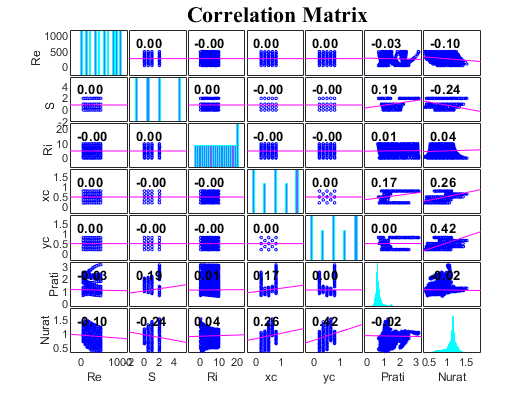

set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
name8=sprintf('D:/Matlab Drive/Research/Figure/Pearson/Pearson.jpg');
exportgraphics(gcf,name8)

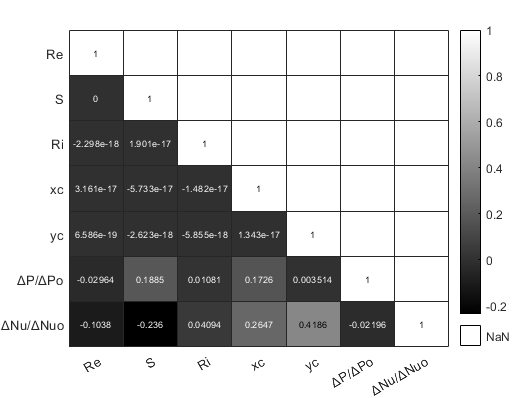

r=table2array(R);
isupper = logical(triu(ones(size(r)),1));
r(isupper) = NaN;
figure()
h=heatmap(r,"Colormap",gray,'MissingDataColor','w');
labels = ["Re","S","Ri","xc","yc","ΔP/ΔPo","ΔNu/ΔNuo"];
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
name9=sprintf('D:/Matlab Drive/Research/Figure/Pearson/heatmap.jpg');
exportgraphics(gcf,name9)

**Box Plot**

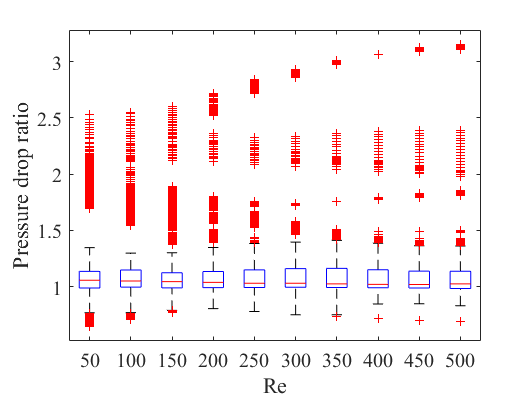

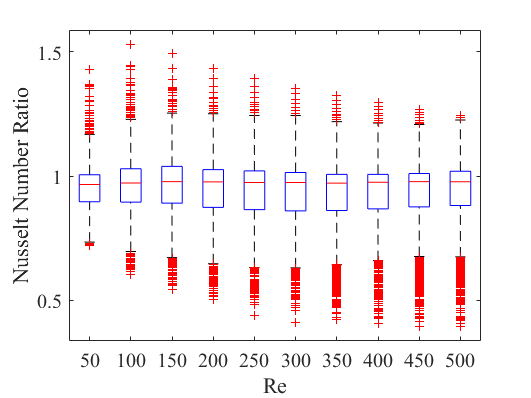

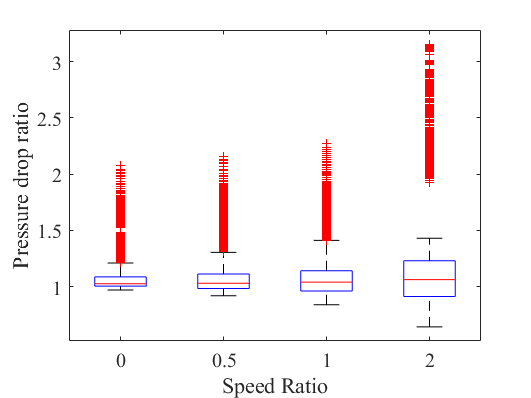

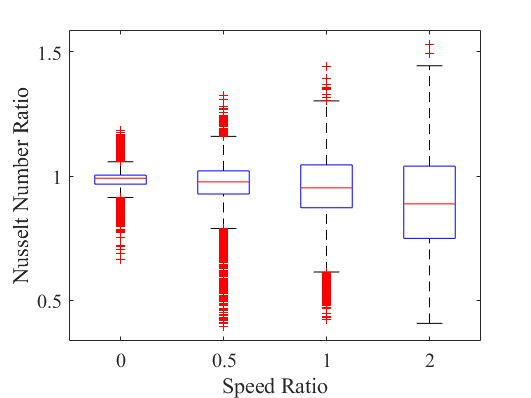

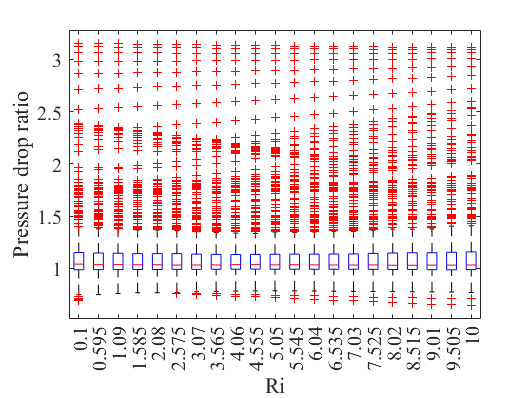

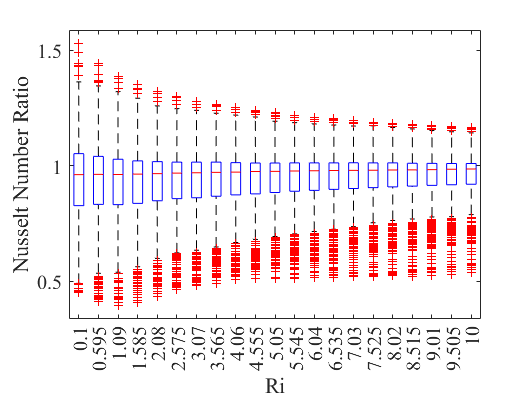

box_plot1=["Re", "Speed Ratio","Ri"];
box_plot2=["Pressure drop ratio","Nusselt Number Ratio"];
for i=1:3
    for j=6:7
        figure()
        boxplot(data_map_array(:,j),data_map_array(:,i))
        set(gca,...
        'Units','normalized',...
        'FontUnits','points',...
        'FontWeight','normal',...
        'FontSize',15,...
        'FontName','Times')
        hold on
        box_plot_name1=sprintf(box_plot1(i));
        box_plot_name2=sprintf(box_plot2(j-5));
        xlabel(box_plot_name1)
        ylabel(box_plot_name2)
        hold off
        clear xlabel
        clear ylabel
        name10=sprintf('D:/Matlab Drive/Research/Figure/Pearson/ %s vs %s boxplot.jpg',box_plot_name1,box_plot_name2);
        exportgraphics(gcf,name10)
    end
end

# **PARAM VS NU**

**Re vs Nu for different Ri x and y position**

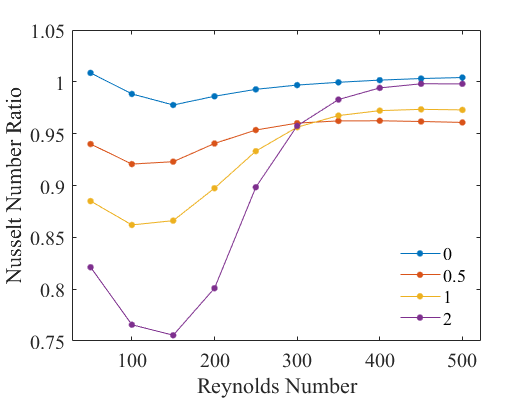

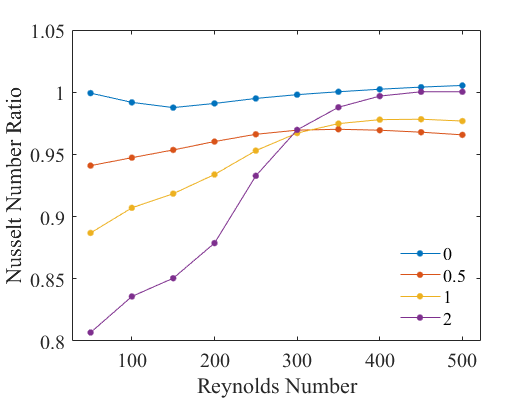

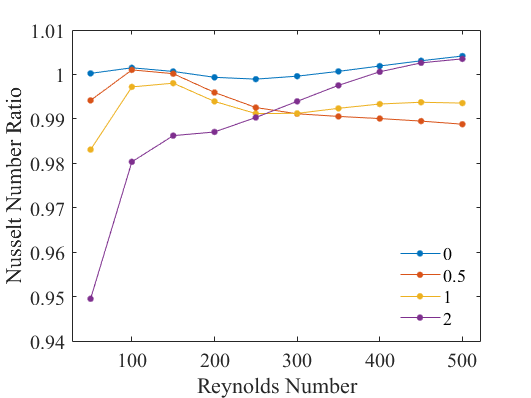

Riset=[0.1,1.09,10];
xcset=[0.2];
ycset=[0.8];
for i=Riset
    for j=xcset
        for k=ycset
            figure();
            data2=data_map_table(data_map_table.Ri==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Re,data2.Nuratio,data2.S);
            set(s,'linestyle','-')
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times')
            xlabel('Reynolds Number')
            ylabel('Nusselt Number Ratio')
%             fig_name=sprintf('Nusselt number variation for different Reynolds numbers for different Ψ for Ri=%.3f Position xc=%.2f and yc=%.2f',i,j,k);
%             title(fig_name);
            legend('location','southeast',"Box","off");
            name1=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Re/ Nu vs Re, Ri= %.3f, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name1)
        end
    end
end

**Ri vs Nu for diff para**

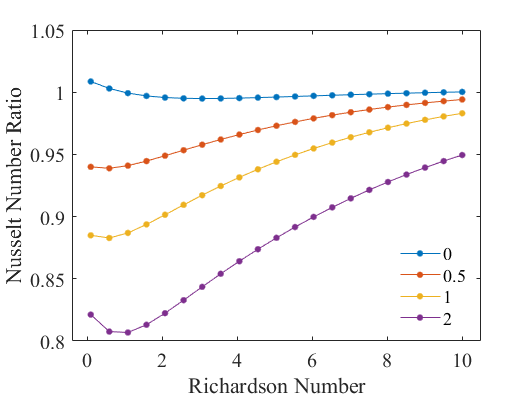

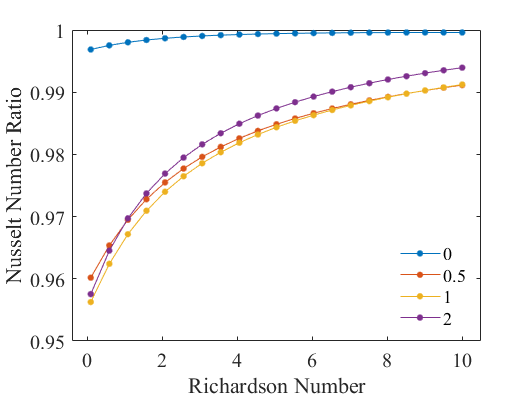

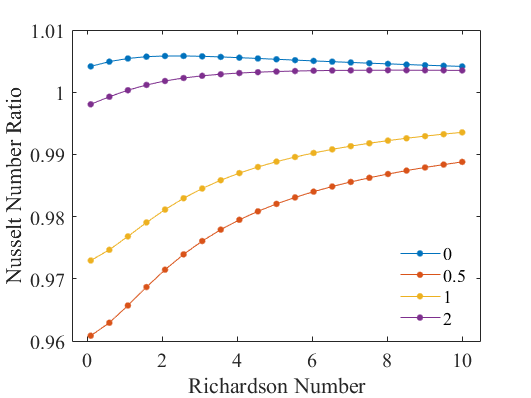

Reset=[50,300,500];
for i=Reset
    for j=xcset
        for k=ycset
            g=figure();
            data2=data_map_table(data_map_table.Re==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Ri,data2.Nuratio,data2.S);
            set(s,'linestyle','-')
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times')
            xlabel('Richardson Number')
            ylabel('Nusselt Number Ratio')
%             str=sprintf('Nusselt number variation for different Richardson numbers for different Ψ for Re=%d Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str);
            legend('location','southeast',"Box","off");
            name2=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Ri/ Nu vs Ri, Re= %d, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name2)
        end
    end
end

**Nu vs Shi**

data5=[];
for i= Riset
    for j=Reset
        data4=data_map_table(data_map_table.xc==0.2 & data_map_table.yc==0.5 & data_map_table.Re==j & data_map_table.Ri==i,:);
        data5=[data5;data4];
    end
end
data5

data5 = 36×7 table
    Re      S      Ri     xc     yc     Pratio     Nuratio
    ___    ___    ____    ___    ___    _______    _______

     50      0     0.1    0.2    0.5     1.0246      1.057
     50    0.5     0.1    0.2    0.5    0.98571    0.95755
     50      1     0.1    0.2    0.5     0.9555    0.88775
     50      2     0.1    0.2    0.5    0.91045    0.83238
    300      0     0.1    0.2    0.5     0.9866    0.96009
    300    0.5     0.1    0.2    0.5    0.93543    0.88154
    300      1     0.1    0.2    0.5     0.8666    0.71777
    300      2     0.1    0.2    0.5    0.74968    0.45873
    500      0     0.1    0.2    0.5     1.0033    0.97684
    500    0.5     0.1    0.2    0.5    0.97037    0.92033
    500      1     0.1    0.2    0

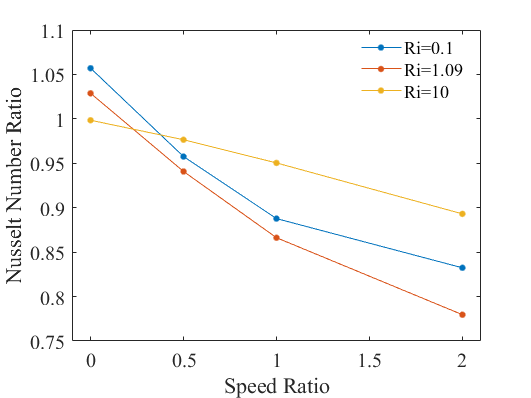

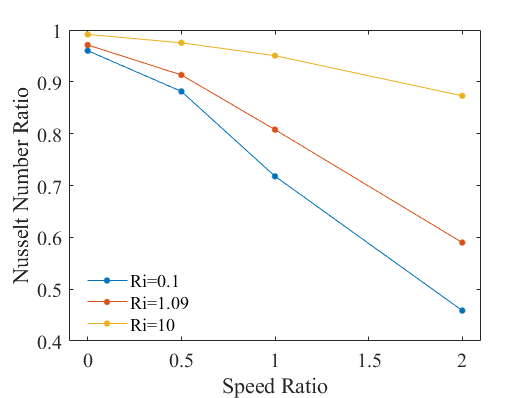

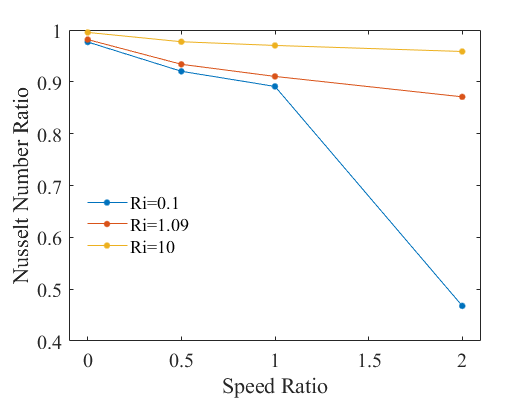

for i=Reset
    figure()
    data3=data5(data5.Re==i,:);
    s=gscatter(data3.S,data3.Nuratio,data3.Ri);
    set(s,'linestyle','-')
    set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
    xlabel("Speed Ratio")
    ylabel("Nusselt Number Ratio")
    legend("Ri=0.1","Ri=1.09","Ri=10",'Box','off')
    name3=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Shi/ Nu vs Shi, Re= %i.jpg',i);
    exportgraphics(gcf,name3)
end

# **PARAM VS P**

**Re vs Nu for different Ri x and y position**

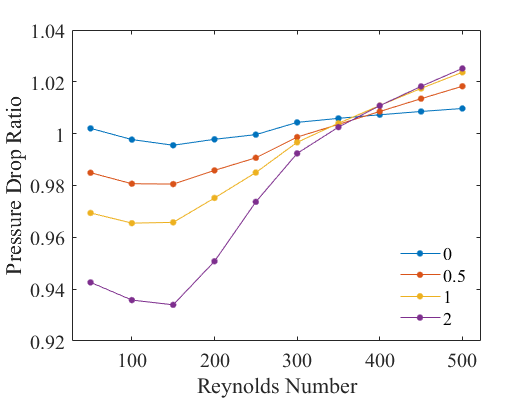

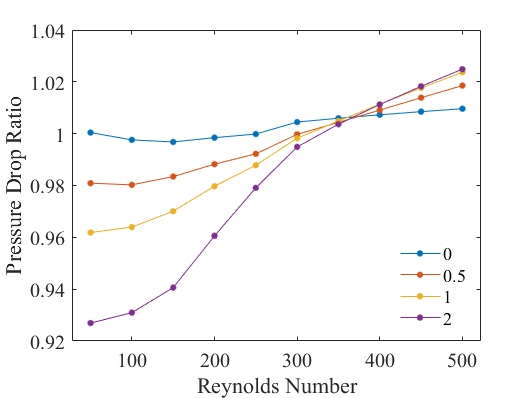

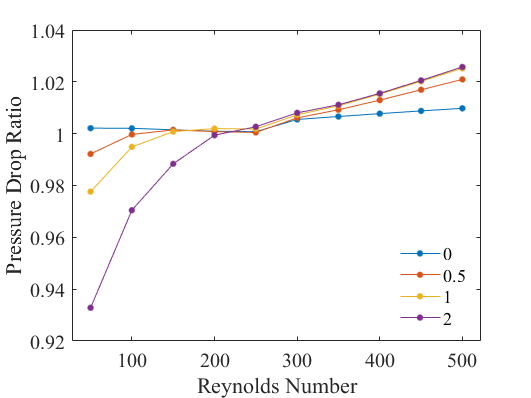

Riset=[0.1,1.09,10];
xcset=[0.2];
ycset=[0.8];
for i=Riset
    for j=xcset
        for k=ycset
            figure();
            data2=data_map_table(data_map_table.Ri==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Re,data2.Pratio,data2.S);
            set(s,'linestyle','-')
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times')
            xlabel('Reynolds Number')
            ylabel('Pressure Drop Ratio')
%             fig_name=sprintf('Nusselt number variation for different Reynolds numbers for different Ψ for Ri=%.3f Position xc=%.2f and yc=%.2f',i,j,k);
%             title(fig_name);
            legend('location','southeast',"Box","off");
            name4=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Re/ P vs Re, Ri= %.3f, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name4)
        end
    end
end

**Ri vs Nu for diff para**

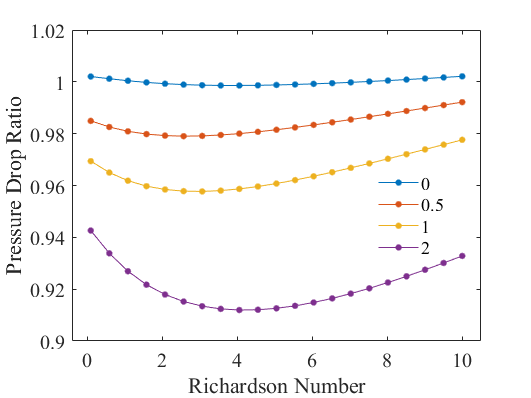

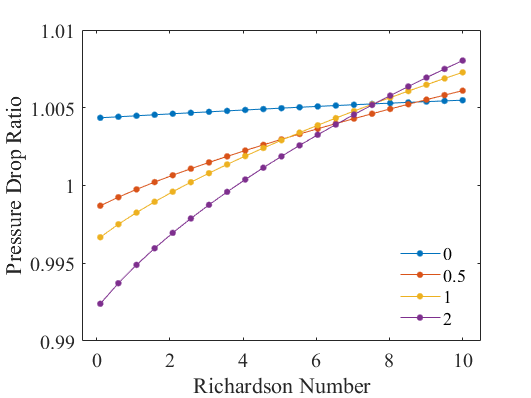

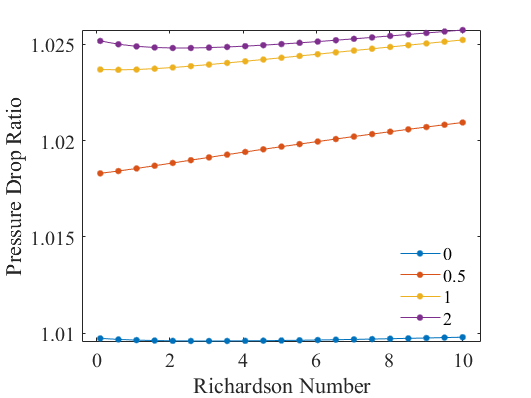

Reset=[50,300,500];
for i=Reset
    for j=xcset
        for k=ycset
            g=figure();
            data2=data_map_table(data_map_table.Re==i& data_map_table.xc==j & data_map_table.yc==k,:);
            s=gscatter(data2.Ri,data2.Pratio,data2.S);
            set(s,'linestyle','-')
            set(gca,...
            'Units','normalized',...
            'FontUnits','points',...
            'FontWeight','normal',...
            'FontSize',15,...
            'FontName','Times')
            xlabel('Richardson Number')
            ylabel('Pressure Drop Ratio')
%             str=sprintf('Nusselt number variation for different Richardson numbers for different Ψ for Re=%d Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str);
            if i==50 
                legend('Position',[0.7 0.42 0.15 0.08],"Box","off");
            else
                legend('location','southeast',"Box","off");
                end
            name5=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Ri/ P vs Ri, Re= %d, xc=%.2f, yc=%.2f.jpg',i,j,k);
            exportgraphics(gcf,name5)
        end
    end
end

**Nu vs Shi**

data5=[];
for i= Riset
    for j=Reset
        data4=data_map_table(data_map_table.xc==0.2 & data_map_table.yc==0.5 & data_map_table.Re==j & data_map_table.Ri==i,:);
        data5=[data5;data4];
    end
end
data5

data5 = 36×7 table
    Re      S      Ri     xc     yc     Pratio     Nuratio
    ___    ___    ____    ___    ___    _______    _______

     50      0     0.1    0.2    0.5     1.0246      1.057
     50    0.5     0.1    0.2    0.5    0.98571    0.95755
     50      1     0.1    0.2    0.5     0.9555    0.88775
     50      2     0.1    0.2    0.5    0.91045    0.83238
    300      0     0.1    0.2    0.5     0.9866    0.96009
    300    0.5     0.1    0.2    0.5    0.93543    0.88154
    300      1     0.1    0.2    0.5     0.8666    0.71777
    300      2     0.1    0.2    0.5    0.74968    0.45873
    500      0     0.1    0.2    0.5     1.0033    0.97684
    500    0.5     0.1    0.2    0.5    0.97037    0.92033
    500      1     0.1    0.2    0

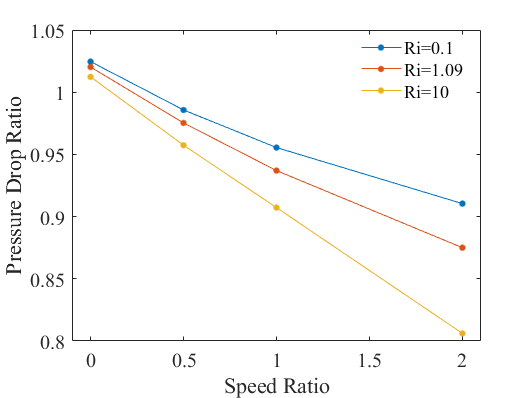

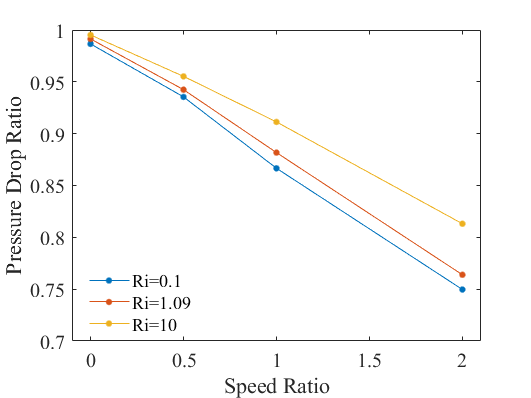

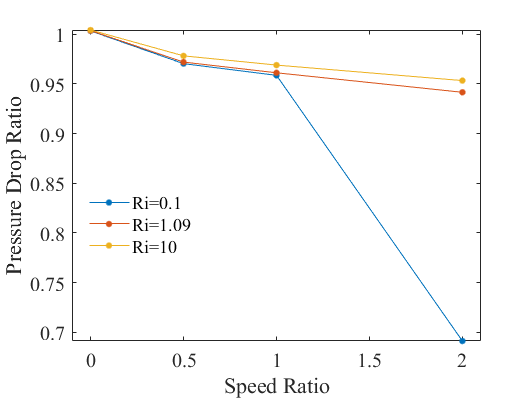

for i=Reset
    figure()
    data3=data5(data5.Re==i,:);
    s=gscatter(data3.S,data3.Pratio,data3.Ri);
    set(s,'linestyle','-')
    set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
    xlabel("Speed Ratio")
    ylabel("Pressure Drop Ratio")
    legend("Ri=0.1","Ri=1.09","Ri=10",'Box','off')
    name6=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Shi/ P vs Shi, Re= %i.jpg',i);
    exportgraphics(gcf,name6)
end

# **Surface Plot**

**Position Vs Nu**

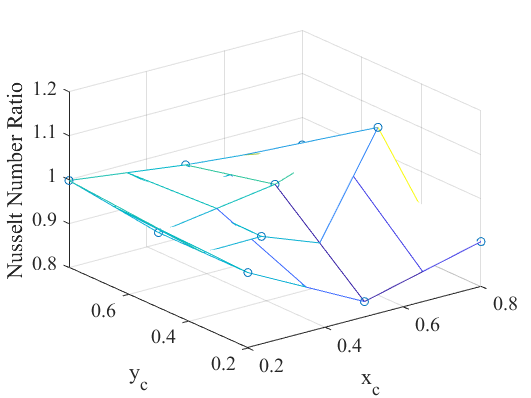

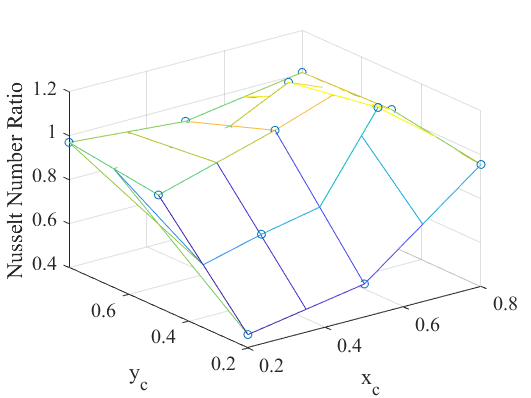

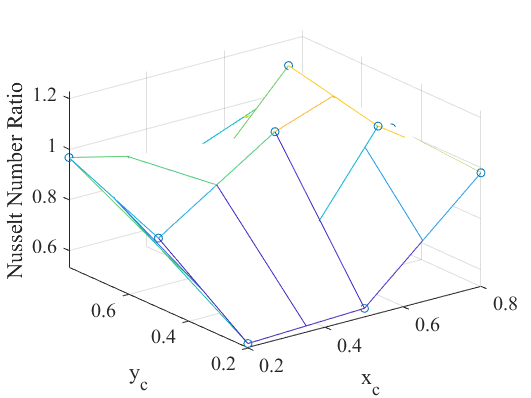

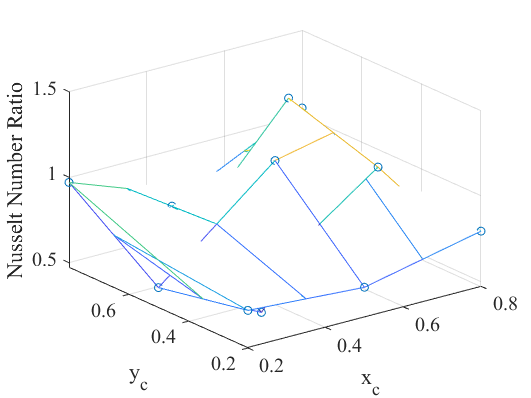

Sset=[0 0.5 1 2];
Reset_surf=[300];
Riset_surf=[1.09];
for i = Reset_surf
    for j= Riset_surf
        for k=Sset
            figure()
            data7=data_map_table(data_map_table.Re==i & data_map_table.Ri==j & data_map_table.S==k,:);
            [xq,yq] = meshgrid(data7.xc,data7.yc);
            vq = griddata(data7.xc,data7.yc,data7.Nuratio,xq,yq);  %(x,y,v) being your original data for plotting points
            mesh(xq,yq,vq)
            hold on
            plot3(data7.xc,data7.yc,data7.Nuratio,'o')
            set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
            xlabel("x_c")
            ylabel("y_c")
            zlabel("Nusselt Number Ratio")
            name7=sprintf('D:/Matlab Drive/Research/Figure/Position vs Nu/ Re=%0.3f, Ri=%0.3f, shi=%0.3f surfaceplot(Nusselt).jpg',i,j,k);
            exportgraphics(gcf,name7)
        end
    end
end

**Position Vs P**

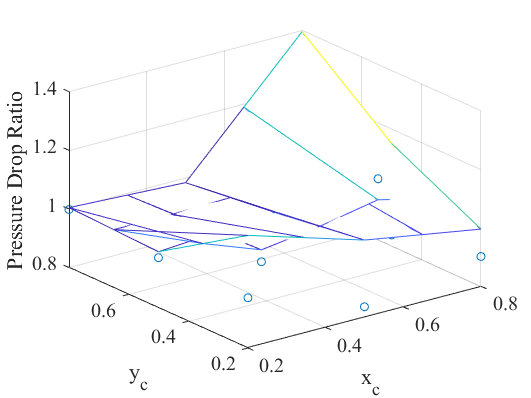

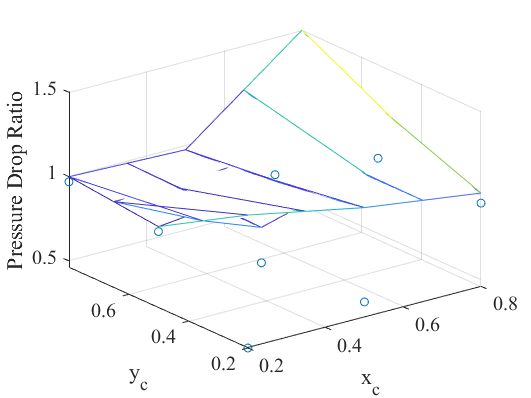

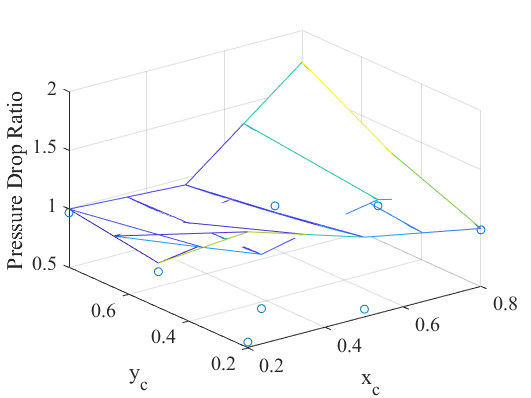

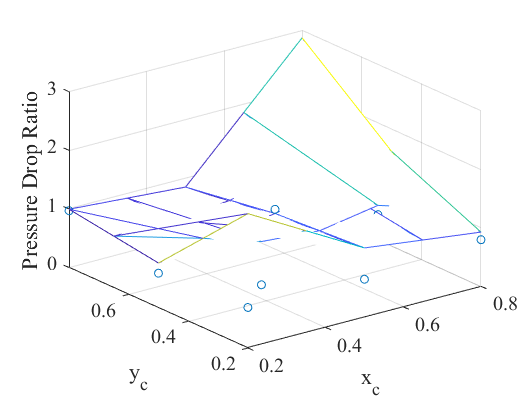

for i = Reset_surf
    for j= Riset_surf
        for k=Sset
            figure()
            data7=data_map_table(data_map_table.Re==i & data_map_table.Ri==j & data_map_table.S==k,:);
            [xq,yq] = meshgrid(data7.xc,data7.yc);
            vq = griddata(data7.xc,data7.yc,data7.Pratio,xq,yq);  %(x,y,v) being your original data for plotting points
            mesh(xq,yq,vq)
            hold on
            plot3(data7.xc,data7.yc,data7.Nuratio,'o')
            set(gca,'Units','normalized','FontUnits','points','FontWeight','normal','Fontsize',15,'FontName','Times')
            xlabel("x_c")
            ylabel("y_c")
            zlabel("Pressure Drop Ratio")
            name7=sprintf('D:/Matlab Drive/Research/Figure/Position vs Nu/ Re=%0.3f, Ri=%0.3f, shi=%0.3f surfaceplot(Pressure).jpg',i,j,k);
            exportgraphics(gcf,name7)
        end
    end
end